### Task1

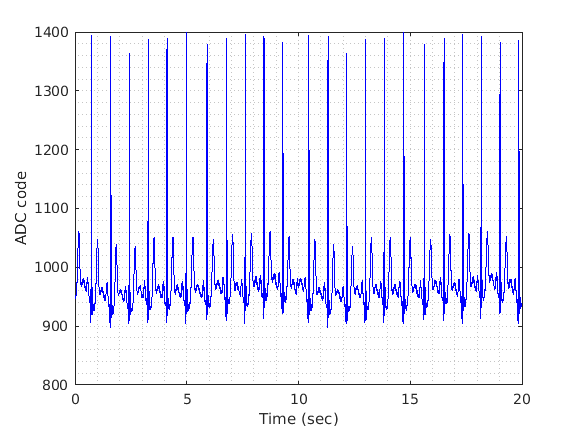

clc
clear all

% plotting ECG1
load ECG_case_1.mat


t = 0:(1/Fs):(length(ECG)-1)*(1/Fs); %time vector for ECG1

plot (t,ECG,"b")
xlabel ("Time (sec)")
ylabel ("ADC code")
grid minor 

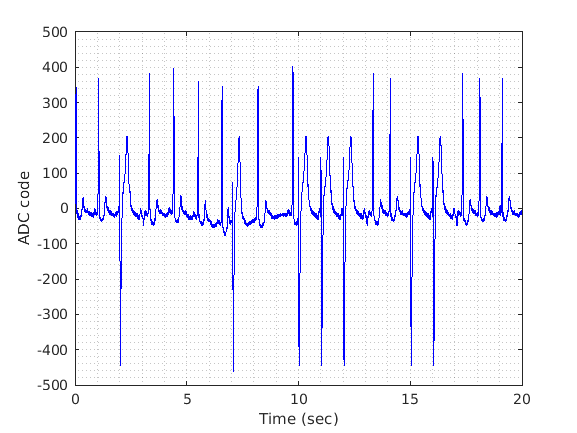


%plotting ECG2
load ECG_case_2.mat

t = 0:(1/Fs):(length(ECG)-1)*(1/Fs); %time vector for ECG2

plot (t,ECG,"b")
xlabel ("Time (sec)")
ylabel ("ADC code")
grid minor 

### Task 2

load ECG_case_1.mat
[x,f] = frft (ECG, Fs);

%filtering out the part that is not withing in 0.5-45Hz range
fcutoff_top = 45;
fcutoff_bottom = 0.5;

diff = f(2) - f(1);

fcutoff_bottomidx = ceil(fcutoff_bottom/diff);
fcutoff_topidx = ceil(fcutoff_top/diff) ;

%equating the parts that aren't in the range to zero
ECGfiltered = x;
ECGfiltered (1 : fcutoff_bottomidx) = 0;
ECGfiltered (fcutoff_topidx : end) = 0;

%ECGfiltered is the final filtered signal
t = 0:(1/Fs):(length(ECG)-1)*(1/Fs);

%finding inverse fourier transform so that we can plot filtered signal
[ECG_filtered,t] = invfrft (ECGfiltered,f,Fs);


%using the number of R peaks to find heart rate
plot (t, ECG_filtered,'b')
MinDist = 280;
[peaks, locations] = findpeaks(ECG_filtered,"MinPeakDistance",MinDist)

peaks =   421.3226  428.6782  401.3376  418.5146  425.2621  427.4339  403.6569  414.7380  417.9965  410.8701  402.8077  426.1016  426.6661  402.4180  418.1369  425.3554  427.7462  403.2941  415.2525  417.3407  411.5474  402.3624  413.8328


locations =          266         577         877        1181        1483        1796        2129        2445        2746        3045        3348        3767        4078        4378        4682        4984        5297        5630        5946        6247        6546        6849        7149


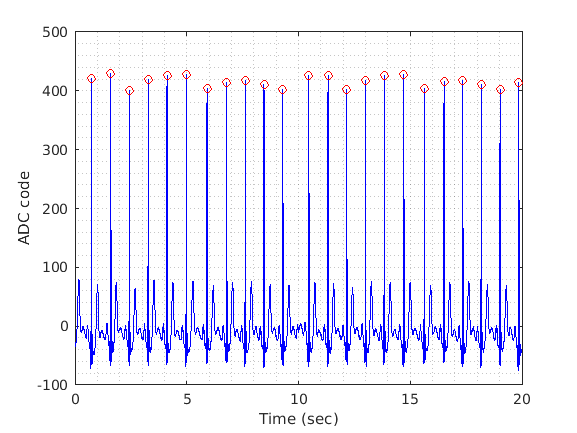

hold on
grid minor

plot (locations/Fs , peaks ,"red o")
xlabel ("Time (sec)")
ylabel ('ADC code')


HeartRate = ((length (peaks))/t(end) * 60)

HeartRate = 69

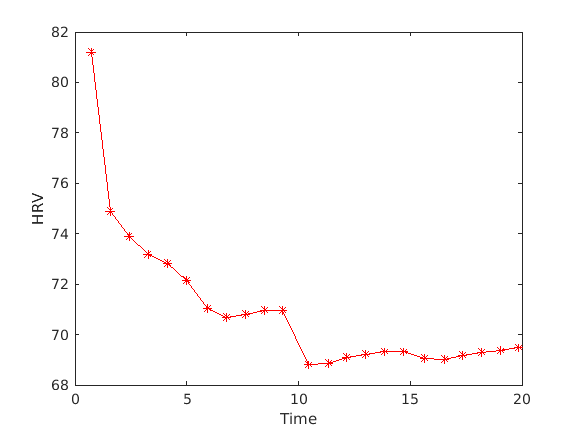


%finding HRV in sample
HRV=[];
for s =1:length(locations)
    i = s/(locations(s)/Fs)*60;
    HRV=[HRV, i];
end

%plotting HRV with time
figure
plot (locations/Fs , HRV,'*-r')
xlabel ('Time')
ylabel ('HRV')

### Task 3

%plot of filtered ECG1 graph for labels of minima and maxima
plot (t, ECG_filtered,'magenta')
ylabel ('ADC code')
xlabel ('Time (sec)')

hold on
grid minor

%finding and plotting R wave on graph
[Rwave, locations] =findpeaks(ECG_filtered,'MinPeakHeight',0.4,'MinPeakDistance',160)

Rwave =    80.0226  421.3226  428.6782  401.3376  418.5146  425.2621  427.4339  403.6569  414.7380  417.9965  410.8701  402.8077    2.8578  426.1016  426.6661  402.4180  418.1369  425.3554  427.7462  403.2941  415.2525  417.3407  411.5474  402.3624  413.8328


locations =           64         266         577         877        1181        1483        1796        2129        2445        2746        3045        3348        3588        3767        4078        4378        4682        4984        5297        5630        5946        6247        6546        6849        7149


plot (locations/Fs , Rwave, "or")

%finding and plotting Twave on graph
[Twave, locations] =findpeaks(ECG_filtered,Fs,'MinPeakWidth',.08,'MinPeakHeight',50)

Twave =    80.0226   71.2357   74.7750   64.3020   77.2766   74.3238   75.4791   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.9803   69.9008   74.2632   76.2288   71.2241   68.9131


locations =     0.1750    1.0083    1.8500    2.6889    3.5361    4.3778    5.2806    6.1889    7.0472    7.8972    8.7306    9.5778   10.7333   11.5750   12.4139   13.2611   14.1028   15.0056   15.9139   16.7722   17.6222   18.4556   19.3000


plot (locations , Twave, "oblack")

%finding and plotting Swave on graph
MinProminence= 10

MinProminence = 10

TF = islocalmin(ECG_filtered,'MinProminence',80)

TF = 1×7201 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


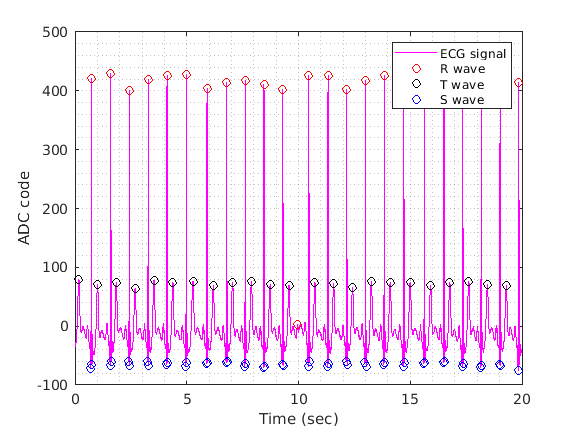

plot (t(TF),ECG_filtered(TF),'oblue')

%adding legend
legend('ECG signal', 'R wave ','T wave ', 'S wave')